% Auto-generated by cameraCalibrator app on 28-Feb-2022
%-------------------------------------------------------


% Define images to process
imageFileNames = {'/Users/sathvikchaganti/Desktop/CV/image6.png',...
    '/Users/sathvikchaganti/Desktop/CV/image12.png',...
    '/Users/sathvikchaganti/Desktop/CV/image11.png',...
    '/Users/sathvikchaganti/Desktop/CV/image10.png',...
    '/Users/sathvikchaganti/Desktop/CV/image9.png',...
    '/Users/sathvikchaganti/Desktop/CV/image8.png',...
    '/Users/sathvikchaganti/Desktop/CV/image7.png',...
    '/Users/sathvikchaganti/Desktop/CV/image5.png',...
    '/Users/sathvikchaganti/Desktop/CV/image4.png',...
    };
% Detect calibration pattern in images
detector = vision.calibration.monocular.CheckerboardDetector();
[imagePoints, imagesUsed] = detectPatternPoints(detector, imageFileNames);

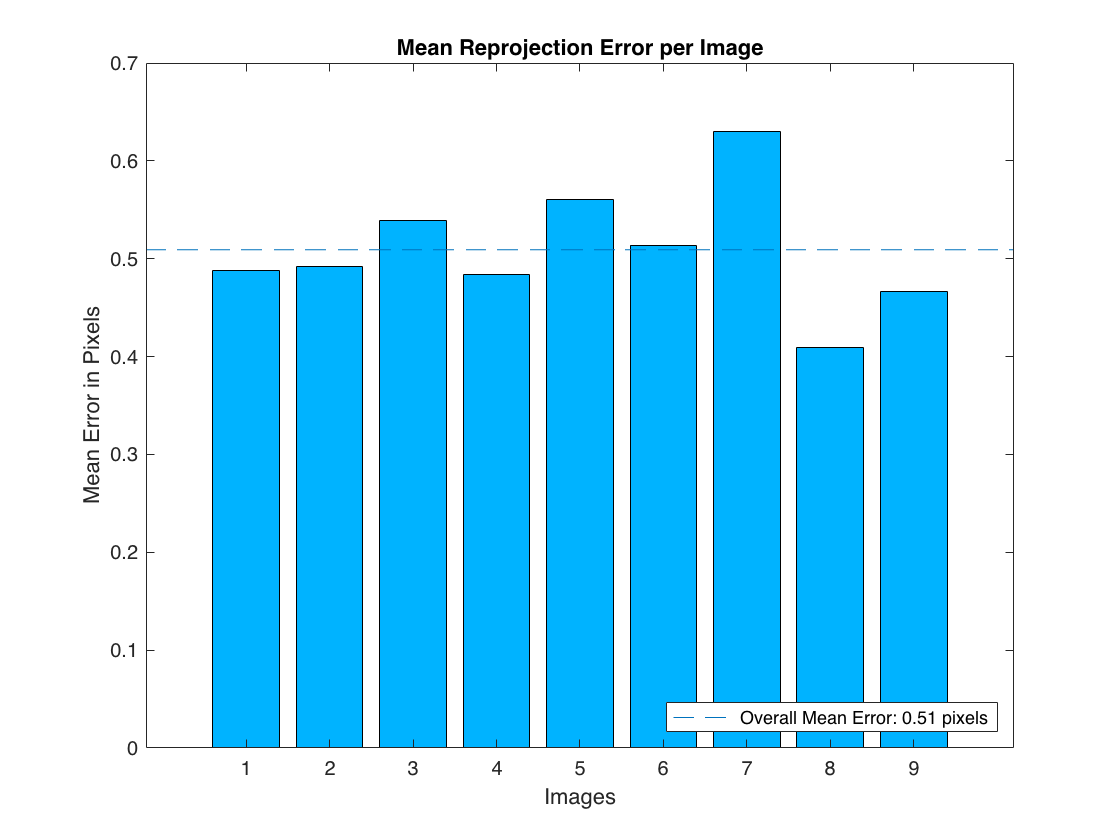

imageFileNames = imageFileNames(imagesUsed);

% Read the first image to obtain image size
originalImage = imread(imageFileNames{1});
[mrows, ncols, ~] = size(originalImage);

% Generate world coordinates for the planar pattern keypoints
squareSize = 25;  % in units of 'millimeters'
worldPoints = generateWorldPoints(detector, 'SquareSize', squareSize);

% Calibrate the camera
[cameraParams, imagesUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', false, 'EstimateTangentialDistortion', false, ...
    'NumRadialDistortionCoefficients', 2, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

% View reprojection errors
h1=figure; showReprojectionErrors(cameraParams);

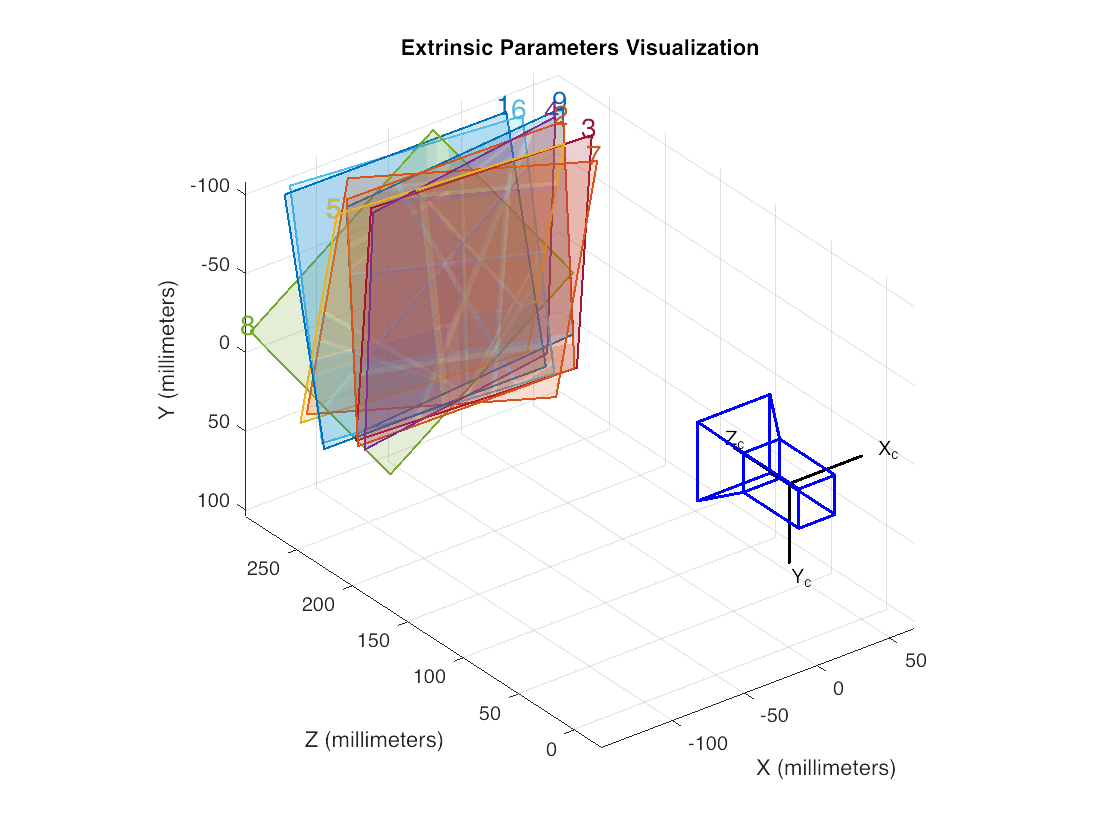


% Visualize pattern locations
h2=figure; showExtrinsics(cameraParams, 'CameraCentric');


% Display parameter estimation errors
displayErrors(estimationErrors, cameraParams);


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [  438.0422 +/- 5.2771      437.8439 +/- 5.2828  ]
Principal point (pixels):[  314.6438 +/- 1.4127      253.8093 +/- 1.3053  ]
Radial distortion:       [    0.0161 +/- 0.0075       -0.1514 +/- 0.0185  ]

Extrinsics
----------
Rotation vectors:
                         [   -0.1566 +/- 0.0030        0.2096 +/- 0.0041        1.5540 +/- 0.0007  ]
                         [   -0.0735 +/- 0.0029        0.0741 +/- 0.0034        1.5896 +/- 0.0006  ]
                         [    0.0628 +/- 0.0029       -0.0189 +/- 0.0032        1.5996 +/- 0.0005  ]
                         [   -0.1309 +/- 0.0035       -0.1583 +/- 0.0038        1.5903 +/- 0.0007  ]
                         [    0.2140 +/- 0.0034        0.0694 +/- 0.0034        0.0131 +/- 0.0007  ]
                         [   -0.1088 +/- 0.0028        0.2667 +/- 0.0041        1.5811 +/- 0.0008  ]
 


% For example, you can use the calibration data to remove effects of lens distortion.
undistortedImage = undistortImage(originalImage, cameraParams);

% See additional examples of how to use the calibration data.  At the prompt type:
% showdemo('MeasuringPlanarObjectsExample')
% showdemo('StructureFromMotionExample')